# Control and Instrumentation Lab Assignment 3

**SWARNENDU PAUL 19EE3FP18**

**1.A.**

The circuit given in Fig.1. ideally represents a series LR circuit while the scope shows the current through the inductor.

Let us assume, the output is $I$ in scope. Then in the addition block the inputs are $IR-L\frac{dI}{dt}$ which is the voltage of the circuit. 

Time constant of the circuit is equal to $\frac{L}{R} = \frac{1mH}{10\Omega} = 10^{-3}s$ 

So we simulate the circuit from -0.02s to 0.02s where the step voltage input was provided at $t = 0s$.

The corresponding simulink file is provided as SeriesLRsimulink.slx

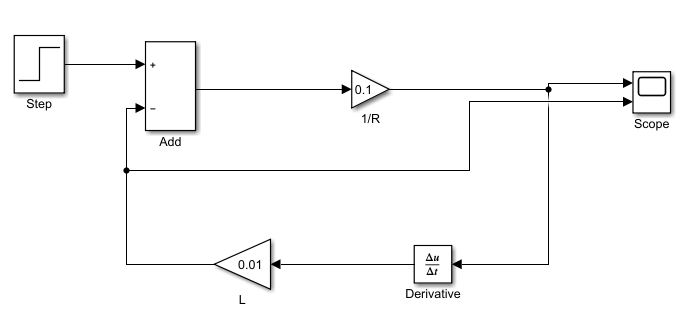

Where the scope outputs provide current through the inductor and voltage across the inductor vs time.

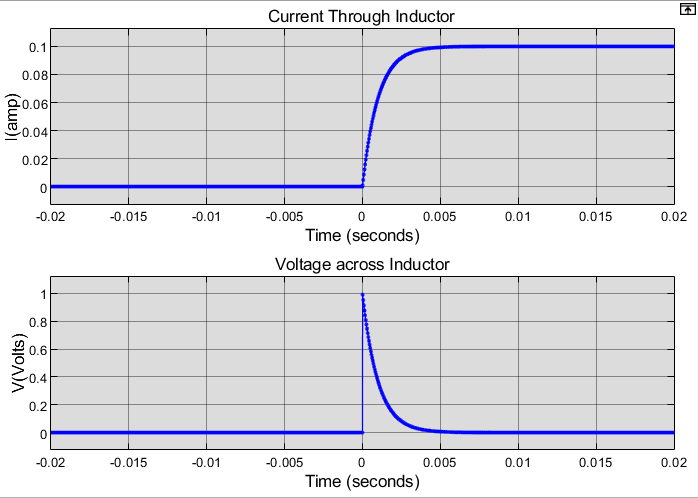

**1.B.**

i. The given transfer function is $G(s) = \frac{(s+1)}{s(s+2)(s+3)}$ 

We will use "tf" and "zpk" command to enter the following transfer functions to matlab.

Here zeros = [-1] poles = [0,-2,-3] and gain = 1

Using tf

tf1=tf([1,1],[1,5,6,0])

tf1 =
 
        s + 1
  -----------------
  s^3 + 5 s^2 + 6 s
 
Continuous-time transfer function.



Using zpk

zpk1=zpk(-1,[0,-2,-3],1)

zpk1 =
 
      (s+1)
  -------------
  s (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



ii. The given transfer function is $G(s) = \frac{-s-1}{s^2+5s+6}$ 

zeros = [-1] poles = [-2,-3] and gain = -1

Using tf

tf2=tf([-1,-1],[1,5,6])

tf2 =
 
     -s - 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.



Using zpk

zpk2=zpk(-1,[-2,-3],-1)

zpk2 =
 
    - (s+1)
  -----------
  (s+2) (s+3)
 
Continuous-time zero/pole/gain model.



**1.C.**

Now our task is to find the state space matrices for both transfer functions tf1 and tf2.

for the first function 'tf1'

[A1, B1, C1, D1]=tf2ss([1,1],[1,5,6,0])

A1 =     -5    -6     0
     1     0     0
     0     1     0


B1 =      1
     0
     0


C1 =      0     1     1


D1 = 0

for the 2nd function 'tf2'

[A2,B2,C2,D2]=tf2ss([-1,-1],[1,5,6])

A2 =     -5    -6
     1     0


B2 =      1
     0


C2 =     -1    -1


D2 = 0